（1）根据第九张PPT中表格所列的QA flag,首先开展对应波段反射率数据（Rrs_xxx）的质量控制；

clear;clc;
filename = "A2017050191000.L2_LAC_OC.nc";
% 查看nc文件信息
info = ncinfo(filename);
% 读取用于质控的flag
l2_flags = ncread(filename, 'geophysical_data/l2_flags');
% 需要用于判断质控的位置
bit_position = [0 1 3 4 5 8 9 12 14 15 16 19 21 22 25];
% 新建用于质控的矩阵
mask = zeros(size(l2_flags));
% 使用for循环，对多个bit位进行质控的筛选
for i = [1:length(bit_position)]
    % 获取该bit位的flag值
    b = bitget(l2_flags,bit_position(i) + 1);
    % 叠加flag
    mask = mask + double(b);
end
% 如果任何一个bit位有质量问题，反映到最后的mask上为该位置处的数值大于0.
% 把mask中大于0的数值置空。
mask(mask>0) = nan;
% 后续对数值读取使用isnan(mask)控制

% 使用NASA OC3M算法需要443, 488, 547波段的数值，对这些波段进行质控。
Rrs_443 = ncread(filename, 'geophysical_data/Rrs_443');
Rrs_488 = ncread(filename, 'geophysical_data/Rrs_488');
Rrs_green = ncread(filename, 'geophysical_data/Rrs_547');

Rrs_443(~isnan(mask)) = nan;
Rrs_488(~isnan(mask)) = nan;
Rrs_green(~isnan(mask)) = nan;

（2）将质量控制后的数据投影到标准经纬网格，像元空间分辨率0.01°

%利用判断的true和false与数相乘的性质，获得blue波段
s=Rrs_443-Rrs_488;
Rrs_blue=(s>0).*Rrs_443+(s<=0).*Rrs_488;
% 读取经纬度数据
lon = ncread(filename, 'navigation_data/longitude');
lat = ncread(filename, 'navigation_data/latitude');
%把blue和green构建插值函数
F1 = scatteredInterpolant(lon(:), lat(:), Rrs_blue(:), 'linear', 'none');
F2 = scatteredInterpolant(lon(:), lat(:), Rrs_green(:), 'linear', 'none');
%构建标准经纬度格网
res=0.01;
xrange=min(min(lon))-5*res:res:max(max(lon))+5*res;
yrange=min(min(lat))-5*res:res:max(max(lat))+5*res;
[xq,yq]= meshgrid(xrange,yrange);
%将原始数据投影到标准经纬度格网
Vq1 = F1(xq, yq);
Vq2 = F2(xq, yq);
%利用 georefcells 函数直接创建R
R=georefcells([min(min(lat))-5*res,max(max(lat))+5*res],[min(min(lon))-5*res,max(max(lon))+5*res],size(Vq1));

（3）基于Lake Nicaragua 矢量文件，裁剪出研究区数据（研究区外的数据mask为NaN）

shp=shaperead("lake nicaragua2.shp","UseGeoCoords",true);

% 获取矢量文件的经纬度范围，并向四周扩大5个单位
shpLonLim=shp.BoundingBox(:,1);shpLatLim=shp.BoundingBox(:,2); % (1)->min,(2)->max
shpLonLim(1)=shpLonLim(1)-5*res;shpLonLim(2)=shpLonLim(2)+5*res;
shpLatLim(1)=shpLatLim(1)-5*res;shpLatLim(2)=shpLatLim(2)+5*res;

% 计算矢量文件范围的左下角、右上角对应像元位置，用于裁切Vq1和Vq2
    % 这里的lat0,lat1和lon0,lon1指的是像元的行列号而不是经纬度
[lat0,lon0]=latlon2pix(R,shpLatLim(1),shpLonLim(1)); % Low Left
[lat1,lon1]=latlon2pix(R,shpLatLim(2),shpLonLim(2)); % Up Right
    % 采用这种舍法才能与后续的格网对应起来，否则矩阵大小会不匹配
lat0=ceil(lat0);lon0=ceil(lon0);lat1=floor(lat1);lon1=floor(lon1);

[shpMat,~]=vec2mtx(shp.Lat,shp.Lon,Vq1,R,"filled"); % 获得矢量文件的矩阵
shpMat=shpMat(lat0:lat1,lon0:lon1); % 根据矢量文件的范围裁切
shpMat(shpMat==2)=NaN;shpMat(shpMat==0)=1; % 使多边形外部为NaN，内部为1

blueMat=Vq1(lat0:lat1,lon0:lon1);greenMat=Vq2(lat0:lat1,lon0:lon1); % 根据矢量文件的范围裁切
blueMat=blueMat.*shpMat;greenMat=greenMat.*shpMat; % 掩膜计算裁切

（4）利用NASA OC3M算法，开展Lake Nicaragua湖区叶绿素浓度的计算

a0=0.2424;a1=-2.7423;a2=1.8017;a3=0.0015;a4=-1.2280; % 参数
f=log10(blueMat./greenMat);
chlor_a=10.^(a0+a1*f.^1+a2*f.^2+a3*f.^3+a4*f.^4);

（5）将计算结果进行伪彩色显示, 使用jet颜色条即可

% 制图
xr2=shpLonLim(1):res:shpLonLim(2);yr2=shpLatLim(1):res:shpLatLim(2);
[xq2,yq2]=meshgrid(xr2,yr2); % 计算裁切后新格网

pcolor(xq2,yq2,chlor_a);
shading flat; 
colormap(jet); 
colorbar; 
axis equal;

（6）将矢量文件叠加显示在结果图上

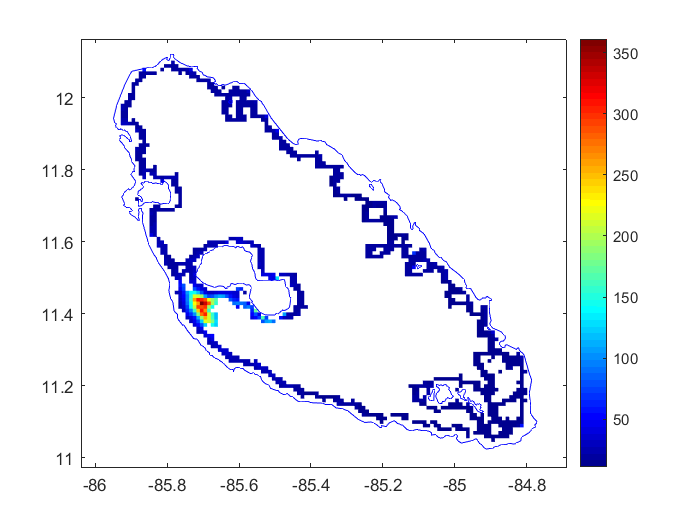

hold on;
geoshow(shp.Lat,shp.Lon);

% 写GeoTIFF文件
% R2=georefcells(shpLatLim,shpLonLim,size(chlor_a)); % 由矢量文件创建新地理参照结构体
% geotiffwrite("ans.tif",chlor_a,R2);